# ASE-4046 Exercise 2 Solutions

## Problem 1

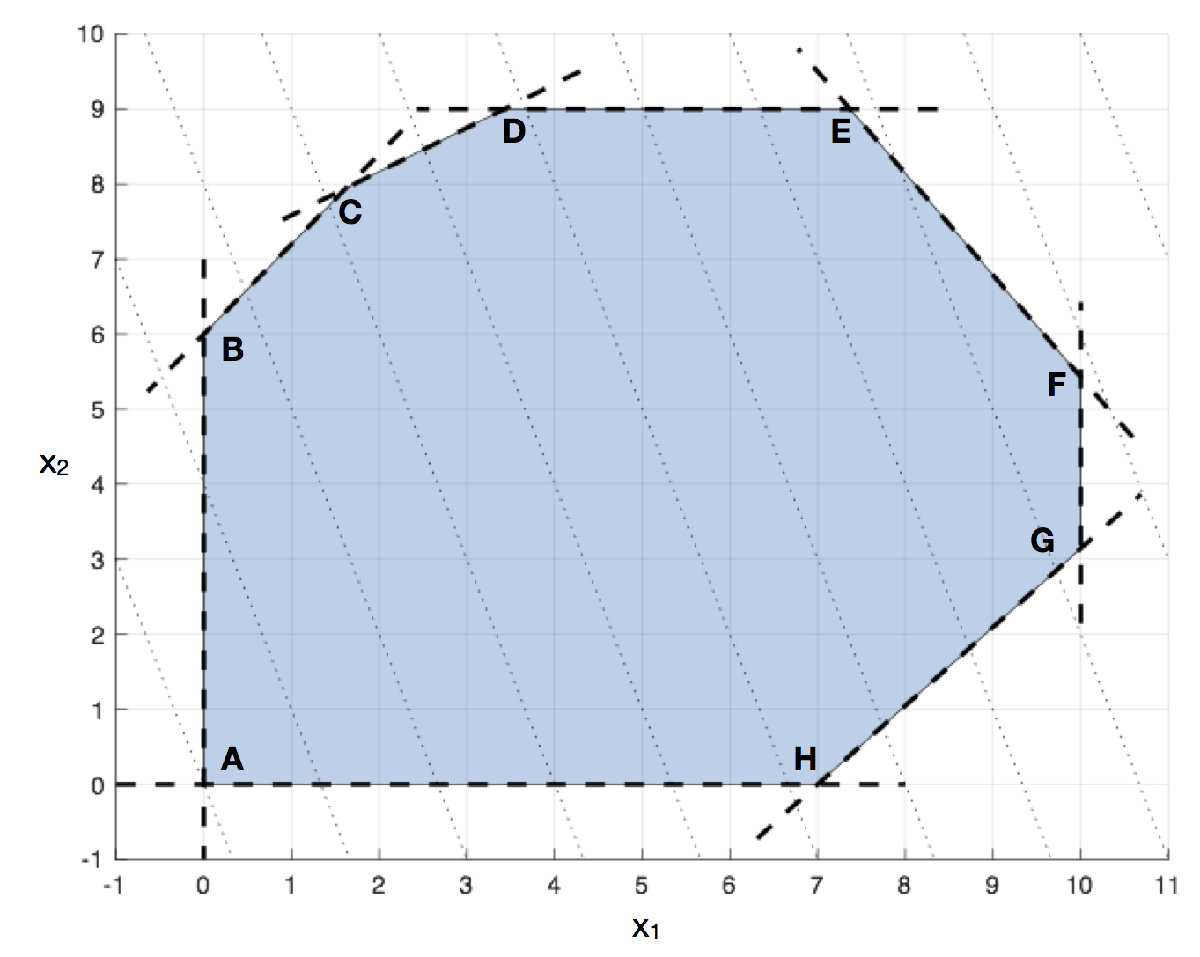

The objective function's contours are shown as dotted lines, and the constraint boundaries as dashed lines. The objective function's value $3x_1+x_2$ increases as one moves up and to the right, so it can be seen that the maximum is achieved at vertex F, which is the intersection of the boundaries of the constraints $x_1\leq 10$ and $19x_1+14x_2\leq 266$. To determine the vertex's $x_2$ value, substitute $x_1=10$ into $19x_1+14x_2= 266$and solve: 

x1=10; x2=(266-19*x1)/14

x2 = 5.4286

  The objective function's value is then

3*x1+x2

ans = 35.4286

## Problem 2

Design variable $x_1$ is the number of servings of oatmeal, $x_2$ the number of servings of chicken, etc.  These should not be negative, so the lower bound vector is

lb=[0,0,0,0,0,0];

The cost function is $f^Tx$ with

f=[0.1; 0.8; 0.4; 0.3; 0.7; 0.6];

The energy, protein, and calcium requirements are inequality constraints $Ax\leq b$with

A= -[110 205 160 160 420 260
      4  32  13   8   4  14
      2  12  54 285  22  80];
b= -[2000; 55; 800];

The restriction of the number of servings is the upper bound vector

ub=[4; 3; 2; 8; 2; 2];

There are no equality constraints $A_{eq}x=b_{eq$ and so 

Aeq=[]; beq=[]; 

Solve for real-valued optimum using `linprog` (Matlab version R2016b). 

[x,fval,exitflag,output,lambda]=linprog(f,A,b,Aeq,beq,lb,ub);

Optimization terminated.


The optimal diet costs

fval

fval = 3.1500

euros and consists of 

x'

ans =     4.0000    0.0000    0.0000    4.5000    2.0000    0.0000


that is, 4 oatmeal, 4.5 milk, and 2 muffin servings. 

The constraints that are active have non-zero Lagrange multipliers. Of the inequality constraints,

lambda.ineqlin

ans =     0.0019
    0.0000
    0.0000


only the energy requirement is active; thus, the cheapest diet exceeds the protein and calcium requirements. To verify this, here are the cheapest diet's energy, protein and calcium amounts and the requirements

[ -A*x -b]

ans =    1.0e+03 *

    2.0000    2.0000
    0.0600    0.0550
    1.3345    0.8000


Of the upper and lower bounds,

[lambda.lower lambda.upper]

ans =     0.0000    0.1062
    0.4156    0.0000
    0.1000    0.0000
    0.0000    0.0000
    0.0000    0.0875
    0.1125    0.0000


the lower-bound (i.e. nonnegativity) constraint is active for chicken, egg, and soup; the upper-bound constraint is active for oatmeal and muffin.

If serving numbers are all required to be integer-values (although the problem statement didn't explicitly say so), the problem should be solved with `intlinprog`.

intcon=1:6;  % all variables constrained to be integer
[x,fval,exitflag]=intlinprog(f,intcon,A,b,Aeq,beq,lb,ub);

LP:                Optimal objective value is 3.150000.                                             

Cut Generation:    Applied 2 mir cuts, and 2 Gomory cuts.                                           
                   Lower bound is 3.300000.                                                         
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



fval, x

fval = 3.3000

x =     4.0000
         0
         0
    5.0000
    2.0000
         0


This diet has 5 servings of milk instead of 4.5 servings, and so is a bit more expensive, 3.30€ instead of 3.15€. 

## Problem 3	

Run the code from the notes of slide 9

url='https://www.cise.ufl.edu/research/sparse/mat/LPnetlib/lp_qap8.mat';
websave('LP_benchmark.mat',url); % save MAT file to current directory
load LP_benchmark   % the data is in variable "Problem"
f=Problem.aux.c; Aeq=Problem.A; beq=Problem.b;
lb=Problem.aux.lo; ub=Problem.aux.hi;
op=optimoptions('linprog','Algorithm','dual-simplex');
tic, x=linprog(f,[],[],Aeq,beq,lb,ub,op); toc


Optimal solution found.

Elapsed time is 1.878460 seconds.


The code is faster if it is not run inside the live editor. When I paste the code into the command window, the elapsed time is 0.7 seconds. 

When I change `qap8` in the first line to `dfl001` and run the code in the command window, the elapsed time is 7.4 s.			